# **Computer Assignment 3 - Signals & Systems - Dr Akhavan**

## ** Amirali Dehghani - 810102443**

### **Question 1**

clc, clearvars, close all;

#### 1 - 1) Creating Mapset

Nch = 32;
mapset = cell(2,Nch);
Alphabet ='abcdefghijklmnopqrstuvwxyz .,!";';
for i = 1:Nch
    mapset{1,i}=Alphabet(i);
    mapset{2,i}=dec2bin(i-1,5);
end

#### 1 - 2) Encoding a picture

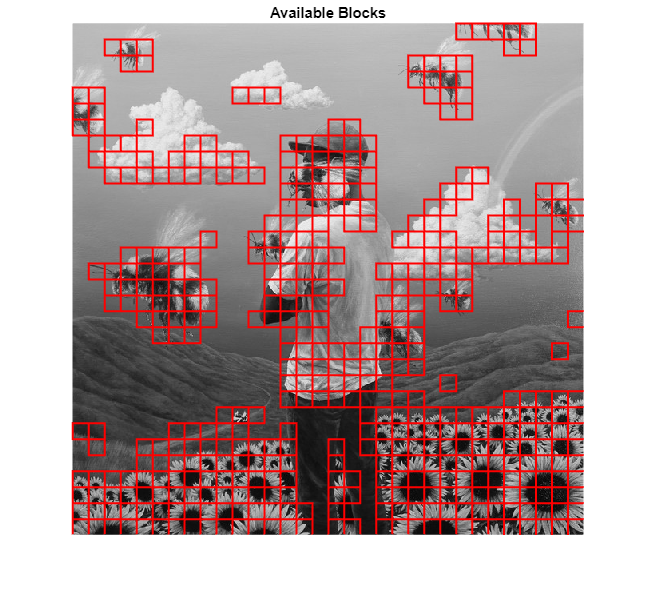

[file, path] = uigetfile({'*.jpg;*.png'}, "Choose your picture: ");
picture = imread([path, file]);
picture = rgb2gray(picture);
message = 'signal;';
codedPicture = coding(picture, message, mapset);

#### Additional) Showing available blocks in photo

#### 1 - 3) Showing original picture and coded picture

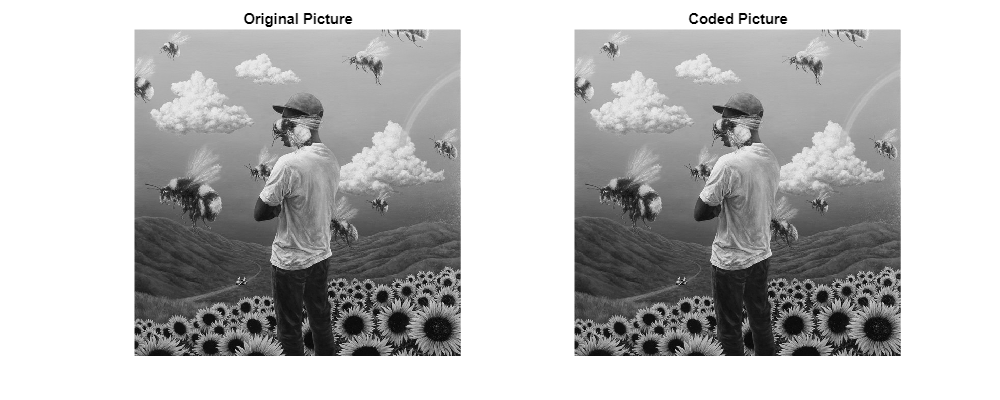

figure('Position', [0 0 1000 400]);
plot1 = subplot(1,2,1);
imshow(picture);
title('Original Picture');
plot2 = subplot(1,2,2);
imshow(codedPicture);
title('Coded Picture');

#### 1 - 4) Decoding the picture

blockSize = 20;
threshold = 100;
message = decoding(codedPicture, mapset, blockSize, threshold);
fprintf('Hidden message is : "%s"', message);

Hidden message is : "signal;"

#### 1 - 5 ) If noise is unintentionally added to the image, can we still decode it?

### Question 2

clc, clearvars, close all;

### Question 3

### Functions

function codedPicture = coding(picture, message, mapset)
    blockSize = 20;
    threshold = 70;
    codedPicture = picture;
    [height, width] = size(picture);
    roundedSize = [floor(height / blockSize) * blockSize, floor(width / blockSize) * blockSize];
    messageLength = length(message);
    binarizedMessage = message2binary(message, mapset);
    availableBlocks = sortBlocks(picture, roundedSize, blockSize, threshold);
    numOfAvailableBlocks = length(availableBlocks);
    if numOfAvailableBlocks < messageLength
        fprintf("You can only fit %d characters in this picture but your message has %d characters.\n", numOfAvailableBlocks, messageLength);
        codedPicture = 1;
        return
    end
    visualizeBlocks(picture, blockSize, threshold);
    messageIndex = 1;
    for i = 1:numOfAvailableBlocks
        block = availableBlocks{i};
        pixels = block('pixels');
        position = block('position'); x = position(1); y = position(2);
        for j = 1:blockSize
            for k = 1:blockSize
                if messageIndex > length(binarizedMessage)
                    break
                end
                pixel = pixels(j, k);
                binarizedPixel = dec2bin(pixel, 8);
                binarizedPixel(end) = binarizedMessage(messageIndex);

                pixels(j, k) = bin2dec(binarizedPixel);
                messageIndex = messageIndex + 1;
            end
            if messageIndex > length(binarizedMessage)
                break
            end
        end
        codedPicture(x : x + blockSize-1, y : y + blockSize-1) = pixels; 
    end
end

function binarizedMessage = message2binary(message, mapset)
    binarizedMessage = '';
    for charInMessage = message
        found = false;
        for charInMapSet = mapset
            if charInMessage == charInMapSet{1};
                binarizedMessage = [binarizedMessage, charInMapSet{2}];
                found = true;
                break;
            end
        end
        if ~found
            fprintf('Character "%c" not found in mapset. Skipping...\n', charInMessage);
        end
    end
end

function message = decoding(codedPicture, mapset, blockSize, threshold)
    [height, width] = size(codedPicture);
    roundedSize = [floor(height / blockSize) * blockSize, floor(width / blockSize) * blockSize];
    codedBlocks = sortBlocks(codedPicture, roundedSize, blockSize, threshold);
    numOfcodedBlocks = length(codedBlocks);
    message = '';
    binarizedChar = '';
    character = '';
    for i = 1:numOfcodedBlocks
        block = codedBlocks{i};
        pixels = block('pixels');
        for j = 1:blockSize
            for k = 1:blockSize
                pixel = pixels(j, k);
                codedPixel = dec2bin(bitand(pixel, 1));
                binarizedChar = [binarizedChar, codedPixel];
                if length(binarizedChar) >= 5
                    character = getCharacter(binarizedChar, mapset);
                    message = [message, character];
                    binarizedChar = '';
                    if character == ';'
                        break
                    end
                end
            end
            if character == ';'
                break
            end
        end
        if character == ';'
            break
        end
    end
end

function availableBlocks = sortBlocks(picture, roundedSize, blockSize, threshold)
    blocks = {}; availableBlocks = {};
    for i = 1:blockSize:roundedSize(1)
        for j = 1:blockSize:roundedSize(2)
            pixels = picture(i:i + blockSize-1, j:j + blockSize-1);
            blockWithoutLSB = bitand(pixels, 254);
            contrast = max(blockWithoutLSB(:)) - min(blockWithoutLSB(:));
            block = containers.Map();
            block('pixels') = pixels;
            block('contrast') = contrast;
            block('position') = [i, j];
            if (contrast > threshold)
                availableBlocks{end+1} = block;
            end
            blocks{end+1} = block;
        end
    end
    contrasts = cellfun(@(block) block('contrast'), availableBlocks);
    [~, sortedIndices] = sort(contrasts, 'descend');
    availableBlocks = availableBlocks(sortedIndices);
end
function character = getCharacter(binary, mapset)
    for char = mapset
        if char{2} == binary
            character = char{1};
            break;
        end
    end 
end

function visualizeBlocks(picture, blockSize, threshold)
    [height, width] = size(picture);
    roundedSize = [floor(height / blockSize) * blockSize, floor(width / blockSize) * blockSize];
    availableBlocks = sortBlocks(picture, roundedSize, blockSize, threshold);

    figure, imshow(picture), title('Available Blocks');
    hold on;

    for i = 1:length(availableBlocks)
        block = availableBlocks{i};
        pos = block('position');
        x = pos(2);
        y = pos(1);
        rectangle('Position', [x, y, blockSize, blockSize], 'EdgeColor', 'r', 'LineWidth', 1.5);
    end
    
    hold off;
end